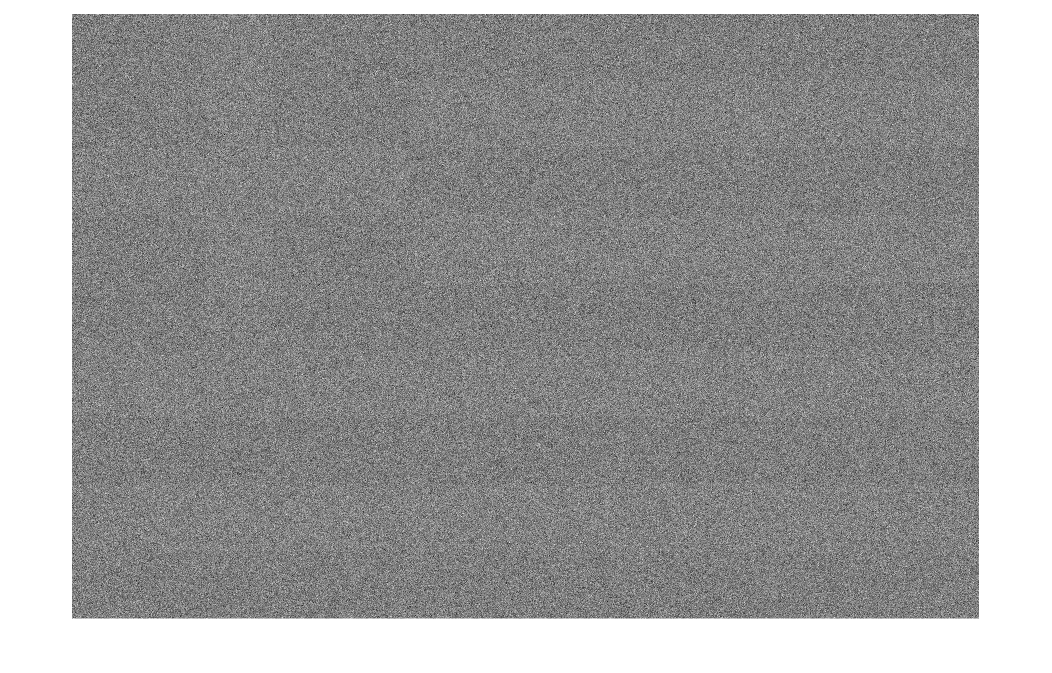

%% Laad foto in en toon deze.
img = double(imread('Geheim.png'))/255;
imshow(img)

%% Bereken de singulierewaardenontbinding.
[U, S, V] = svd(img);

% Toon singuliere waarden.
singuliere_waarden = diag(S);
disp(singuliere_waarden(1:10));

   5.5379e+02
   5.9317e+00
   4.5455e+00
   4.1641e+00
   4.1591e+00
   4.1573e+00
   4.1518e+00
   4.1505e+00
   4.1471e+00
   4.1456e+00



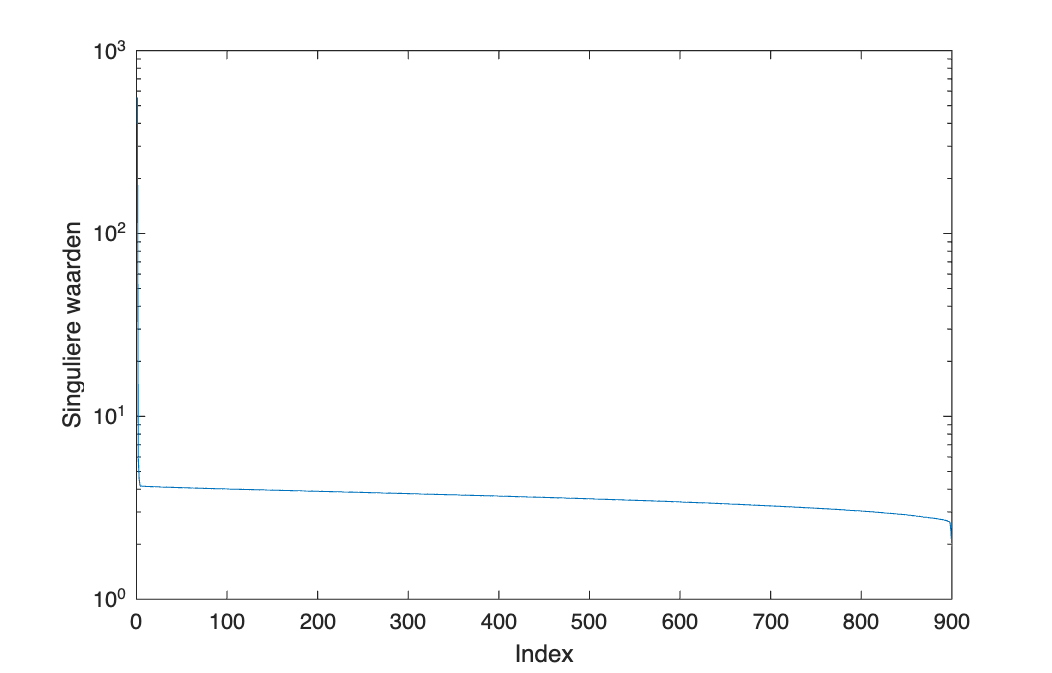

semilogy(singuliere_waarden)
xlabel('Index')
ylabel('Singuliere waarden')

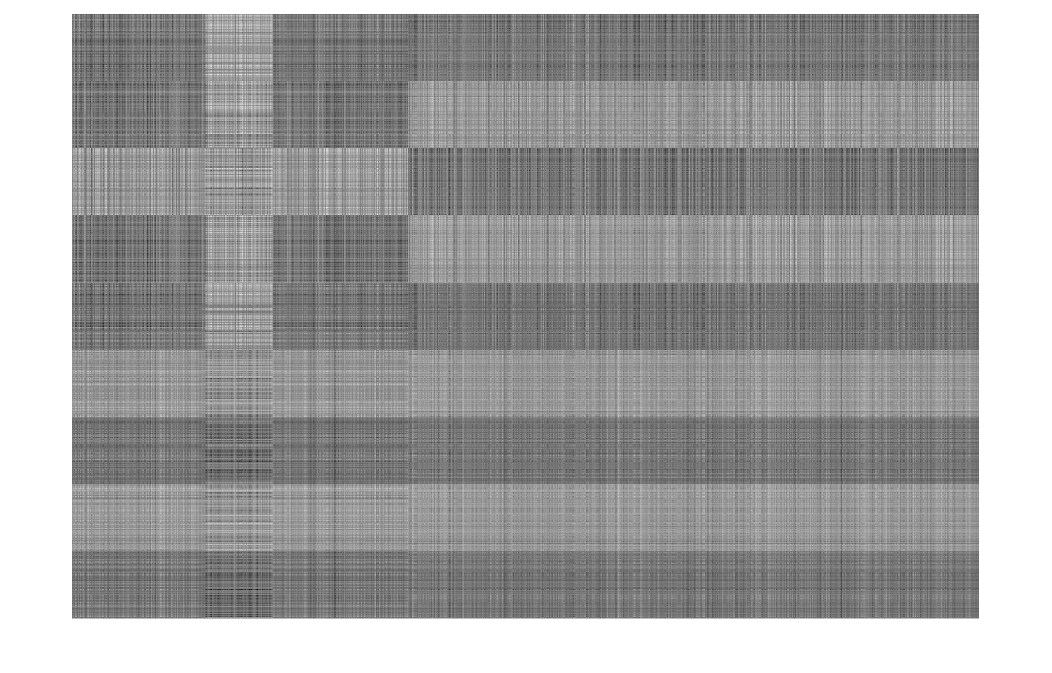

%% Kies compressie en bekijk resultaten.
R = 3; % Selecteer benaderingsrang.

% Voer compressie uit.
Uc = U(:, 1:R);
Sc = S(1:R, 1:R);
Vc = V(:, 1:R);
img_compressed = Uc * Sc * Vc';
img_compressed = rescale(img_compressed);

% Toon gecomprimeerd beeld.
imshow(img_compressed)


% Bereken compressiefactor.
compressiefactor = numel(img) / (numel(Uc) + numel(Sc) + numel(Vc));
fprintf('Het beeld is %2.2f keer kleiner', compressiefactor);

Het beeld is 179.76 keer kleiner